close all

syms xdata ydata
xdata = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
ydata = [1,3,25,72,222,282,256,233,189,123,70,25,11,4];

pop = 763

pop = 763

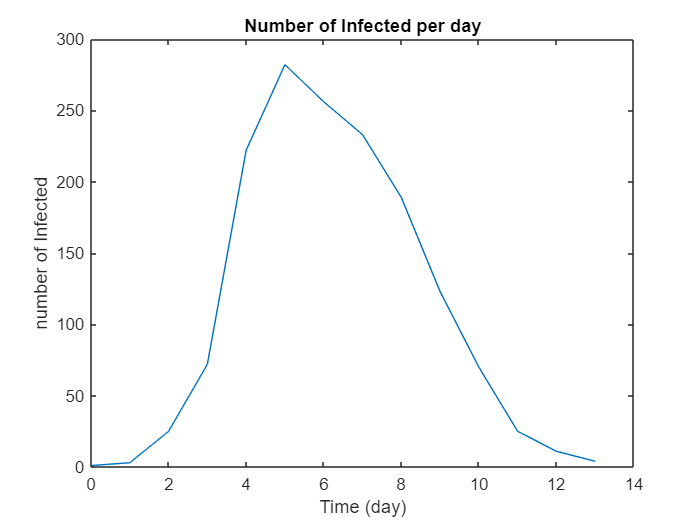


a = 0.003;
b = 0.4;
xt0 = [762, 1, 0];

%Assume v% of infected students are bedridden
v = 100;

plot(xdata, min((100/v)*ydata, pop))
xlabel('Time (day)')
ylabel('number of Infected')
title("Number of Infected per day")

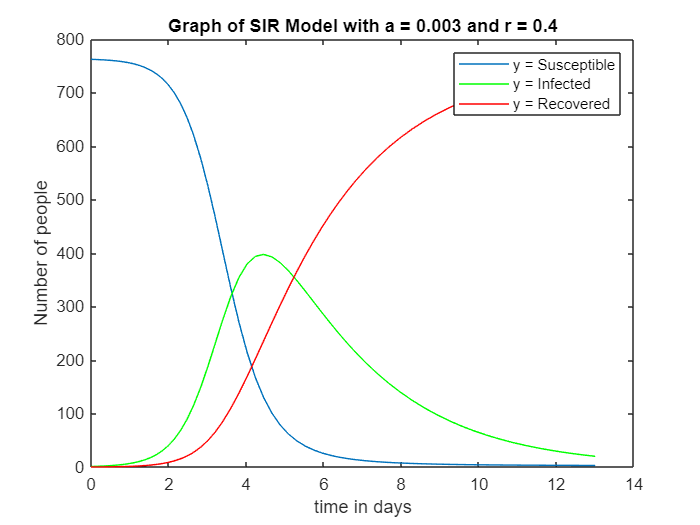

f = @(t,x) [-a*x(1)*x(2);a*x(1)*x(2)-b*x(2);b*x(2)];

[t,xa]=ode45(f,[0 13], xt0);
 plot(t,min(xa(:,1), pop))
 hold on
 plot(t,min(xa(:,2), pop),'g')
 plot(t,min(xa(:,3), pop),'r')
 title('Graph of SIR Model with a = 0.003 and r = 0.4')
 xlabel('Time in days')
 ylabel('Number of people')
 legend({'y = Susceptible','y = Infected', 'y = Recovered'},'Location','northeast')
 hold off



xdata = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
ydata = [1,3,25,72,222,282,256,233,189,123,70,25,11,4];

y(1) = a;
y(2) = b;

[abest, xbest] = lsqcurvefit(@sirfunction2, [a,b] ,xdata, min((100/v)*ydata, pop), [0,0]);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('New parameters: %f, %f',[abest(1), abest(2)])

New parameters: 0.002566, 0.482895

fprintf('Original parameters: %f, %f',[a,b])

Original parameters: 0.003000, 0.400000


a = abest(1)

a = 0.0026

b = abest(2)

b = 0.4829

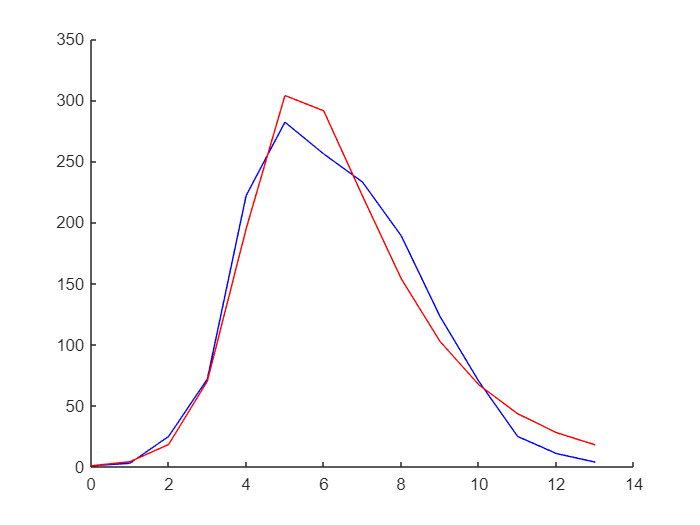


figure
hold on
plot(xdata, min((100/v)*ydata, pop), 'b')
plot(xdata, min(sirfunction2([a,b], xdata), pop), 'r')

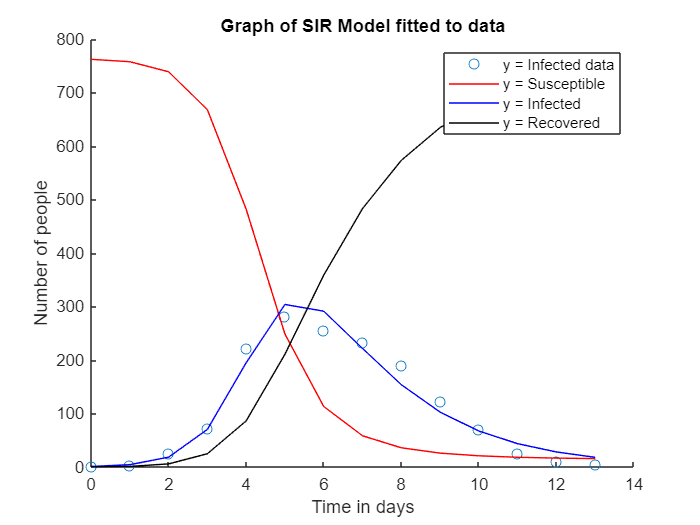

figure
hold on
plot(xdata, min((100/v)*ydata, pop), 'o')
plot(xdata, min(sirfunction([a,b], xdata), pop), 'r')
plot(xdata, min(sirfunction2([a,b], xdata), pop), 'b')
plot(xdata, min(sirfunction3([a,b], xdata), pop), 'k')

title('Graph of SIR Model fitted to data')
 xlabel('Time in days')
 ylabel('Number of people')
 legend({'y = Infected data','y = Susceptible','y = Infected', 'y = Recovered'},'Location','northeast')


(sirfunction([a,b], xdata) + sirfunction2([a,b], xdata) + sirfunction3([a,b], xdata))/pop

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


R0 = a/b

R0 = 0.0053


RSS = sum((min((100/v)*ydata, pop) - min(sirsfunction2([a,b,c], xdata), pop)).^2);
TSS = sum((min((100/v)*ydata, pop) - min((100/v)*mean(ydata), pop)).^2);
R_sq = 1 - (RSS/TSS)

R_sq = 0.9651